**ENGN1930B Lab 2**

**Name: Kuan-Min Lee**

**Instructor: Dr. Jonghwan Lee**

**Lab Introduction:**

In this experiment, the resolution of the smart phone will be investigated by observing a set of sample testing images of USAF resolution target. To start the experiment, the device that is tested is the iPhone 8 model, and its resolution will be investigated further by the images it takes.

**Testing of Resolution of Camera:**

In this section, different condition of images will be investigated. The different setting includes: zoom level of camera, lighting condition, and brightness of the background paper.

The following are the introduction of the experiment settings:

**Zoom Levels:**

Three different zoom level are introduced to the experiment. They are **Zoom Level 1 (no zoom), Zoom Level 2 (one optical zoom, in this case, 2x), and Zoom Level 3 (one added digital zoom).**

**Lighting Condition:**

Two lighting conditions are utilized. The nonlight sample are images taken **without the usage of flashlight of the camera**. The light sample are images taken **with the usage of the flashlight**.

**Brightness of Background Paper:**

In this experiment, two background paper are utilized: **white and black papers.**

**Different zoom levels:**

In this section of the experiment, a set of images with the same background, same object, but different zoom level setting will be investigated to see the variance of the observed pixel size.

**Zoom Level 1 with black background:**

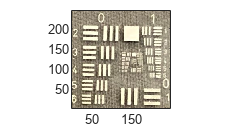

clear all
% read in testing image for zoom level 1 in black ground
allfiles=dir("Test_Images/zoom_lvl_1_*.JPG");
num_files=length(allfiles); % find out how many files in the directory

% read in image
curr_file=allfiles(1).name; % get out the filename of the current image
curr_img=imread(string(curr_file)); % read in the image 
% conduct analysis on image
curr_img=double(curr_img); % convert the image to double type
[num_px,num_py] = size(curr_img); % get the number of pixel in x and y axis
% visualization of the image
figure(1);
curr_img=flip(curr_img,2);
ver_img=flipud(curr_img);
ori_img=flip(ver_img,2);
imagesc(uint8(ori_img))
set(gca,'ydir','normal');  
axis image;  

From the above observation, the bar of the target starts to get blurry from group 2. Therefore, group 2 and 3 will be taken to observe the peak of the image intensity.

test_img=flip(curr_img,2); % flip the image to get the image to the right orientation to the coordinate

% mark out the center of the bar
group2_x_cen=130; % group 2 x center
group2_y_lim=[89.8 143.4]; % group 2 limit range
group3_x_cen=172; % group 3
group3_y_lim=[106.6 143.1];

% convert the image to grayscale image to view its intensity 
bw_img=rgb2gray(uint8(test_img));
% plot the peak for image intensity 
figure;
subplot(211);
    I = bw_img(group2_y_lim(1):group2_y_lim(2),group2_x_cen);  % 1D array extracted from the 2D array.

    I=flip(I,1);
    I=double(I);
    plot(I);
    [pks,locs] = findpeaks(I);  % find peaks.
    line(locs,pks,'linestyle','none','marker','o','color','r');
    grid on;
subplot(212);  % repeat the same for the 3.2-um pattern
    I = bw_img(group3_y_lim(1):group3_y_lim(2),group3_x_cen);

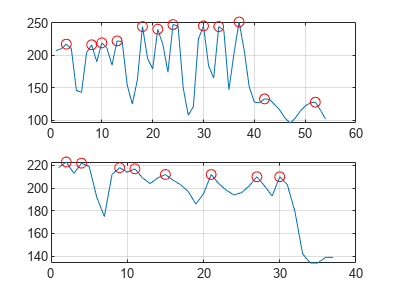

    I=flip(I,2);
    I=double(I);
    plot(I);
    [pks,locs] = findpeaks(I);
    line(locs,pks,'linestyle','none','marker','o','color','r');
    grid on;

The same criterion is utilized for horizontal direction as well:

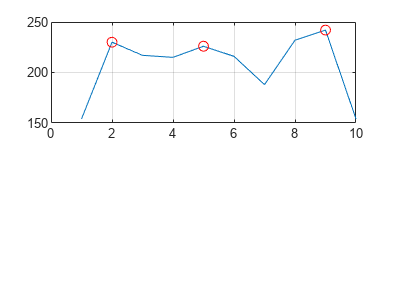

% find out horizontal resolution
group2_3_x_lim=[136 145];
group2_3_y_cen=124;

% plot the peak for image intensity 
figure;
subplot(211);
    I = bw_img(group2_3_y_cen,group2_3_x_lim(1):group2_3_x_lim(2));  % 1D array extracted from the 2D array.
    I=flip(I,1);
    I=double(I);
    plot(I);
    [pks,locs] = findpeaks(I);  % find peaks.
    line(locs,pks,'linestyle','none','marker','o','color','r');
    grid on;

From the above plot, it can be seen that for group 3, the peak-to-valley ratio doesn't follow the 25% Rayleigh criterion. Therefore, the resolution of the camera of the device can't be the same as the resolution of the group 3 resolution. 

For vertical direction, in group 2, the peak-to-valley ratio follows the 25% dip Rayleigh criterion. Therefore, the resolution of the camera falls in group 2 of USAF resolution target, and based on the plot, the line starts to decline at the thrid set of serial waves. Therefore, the resolution falls in element 4 in group 2.

Its resolution in this case can be calculated based on the resolution formula for USAF 1951 target as follow:

group=2; % group 2 in USAF target
element=4; % element 4 in group 2
resolution=2^(group+(element-1)/6);
msg=strcat("The resolution is ", string(resolution), " lp/mm (in vertical)");
msg

msg = "The resolution is 5.6569 lp/mm (in vertical)"

For horizontal direction, in group 2, the peak-to-valley ratio follows the 25% Rayleigh criterion is in element 2 in group 3. Therefore,

group=2; % group 2 in USAF target
element=3; % element 3 in group 2
resolution=2^(group+(element-1)/6);
msg=strcat("The resolution is ", string(resolution), " lp/mm (in horizontal)");
msg

msg = "The resolution is 5.0397 lp/mm (in horizontal)"

**Zoom Level 2 with black background:**

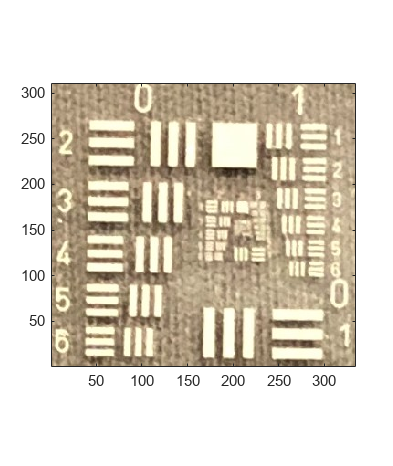

clear all
% read in testing image for zoom level 1 in black ground
allfiles=dir("Test_Images/zoom_lvl_2_*.JPG");
num_files=length(allfiles); % find out how many files in the directory

% read in image
curr_file=allfiles(1).name; % get out the filename of the current image
curr_img=imread(string(curr_file)); % read in the image 
% conduct analysis on image
curr_img=double(curr_img); % convert the image to double type
[num_px,num_py] = size(curr_img); % get the number of pixel in x and y axis
% visualization of the image
figure(2);
curr_img=flip(curr_img,2);
ver_img=flipud(curr_img);
ori_img=flip(ver_img,2);
imagesc(uint8(ori_img))
set(gca,'ydir','normal');  
axis image;  

For the vertical direction, the following plot is obtained:

test_img=flip(curr_img,2); % flip the image to get the image to the right orientation to the coordinate

% mark out the center of the bar
group2_x_cen=178; % group 2 x center
group2_y_lim=[117.0 184.5]; % group 2 limit range

% convert the image to grayscale image to view its intensity 
bw_img=rgb2gray(uint8(test_img));
% plot the peak for image intensity 
figure;
subplot(211);
    I = bw_img(group2_y_lim(1):group2_y_lim(2),group2_x_cen);  % 1D array extracted from the 2D array.

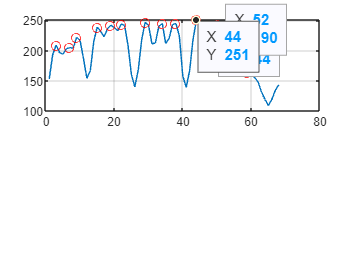

    I=flip(I,1);
    I=double(I);
    plot(I);
    [pks,locs] = findpeaks(I);  % find peaks.
    line(locs,pks,'linestyle','none','marker','o','color','r');
    grid on;

The same criterion is utilized for horizontal direction as well:

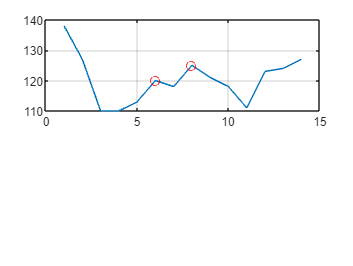

% find out horizontal resolution
group2_3_x_lim=[184 197];
group2_3_y_cen=159;
% plot the peak for image intensity 
figure;
subplot(211);
    I = bw_img(group2_2_y_cen,group2_2_x_lim(1):group2_2_x_lim(2));  % 1D array extracted from the 2D array.
    I=flip(I,1);
    I=double(I);
    plot(I);
    [pks,locs] = findpeaks(I);  % find peaks.
    line(locs,pks,'linestyle','none','marker','o','color','r');
    grid on;

For vertical direction, in group 2, the peak-to-valley ratio follows the 25% dip Rayleigh criterion. Therefore, the resolution of the camera falls in group 2 of USAF resolution target, and based on the plot, the line starts to decline at the thrid set of serial waves. Therefore, the resolution falls in element 4 in group 2.

Its resolution in this case can be calculated based on the resolution formula for USAF 1951 target as follow:

group=2; % group 2 in USAF target
element=4; % element 4 in group 2
resolution=2^(group+(element-1)/6);
msg=strcat("The resolution is ", string(resolution), " lp/mm (in vertical)");
msg

msg = "The resolution is 5.6569 lp/mm (in vertical)"

For horizontal direction, in group 2, the peak-to-valley ratio follows the 25% Rayleigh criterion is in element 2 in group 3. Therefore,

group=2; % group 2 in USAF target
element=3; % element 3 in group 2
resolution=2^(group+(element-1)/6);
msg=strcat("The resolution is ", string(resolution), " lp/mm (in horizontal)");
msg

msg = "The resolution is 5.0397 lp/mm (in horizontal)"

**Zoom Level 3 with black background:**

The same procedure follows in this sample as well:

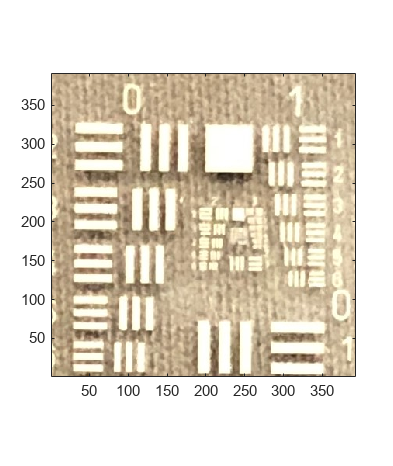

clear all
% read in testing image for zoom level 1 in black ground
allfiles=dir("Test_Images/zoom_lvl_3_*.JPG");
num_files=length(allfiles); % find out how many files in the directory

% read in image
curr_file=allfiles(1).name; % get out the filename of the current image
curr_img=imread(string(curr_file)); % read in the image 
% conduct analysis on image
curr_img=double(curr_img); % convert the image to double type
[num_px,num_py] = size(curr_img); % get the number of pixel in x and y axis
% visualization of the image
figure(3);
curr_img=flip(curr_img,2);
ver_img=flipud(curr_img);
ori_img=flip(ver_img,2);
imagesc(uint8(ori_img))
set(gca,'ydir','normal');  
axis image;  

For the vertical direction of the image, in this zoom level, the image get more influence from the external light source. By this affect, the resolution is affected as well. 

From the above, it can be seen that the resolution is restricted to group 1 and it's about at the 5th element.

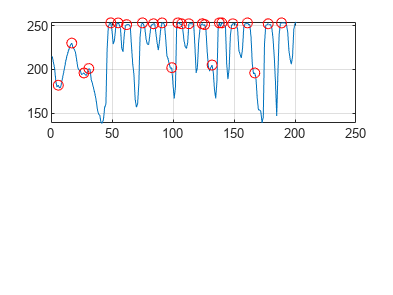

test_img=flip(curr_img,2); % flip the image to get the image to the right orientation to the coordinate

% mark out the center of the bar
group1_x_cen=338; % group 1 x center
group1_y_lim=[120 320]; % group 1 limit range

% convert the image to grayscale image to view its intensity 
bw_img=rgb2gray(uint8(test_img));
% plot the peak for image intensity 
figure;
subplot(211);
    I = bw_img(group1_y_lim(1):group1_y_lim(2),group1_x_cen);  % 1D array extracted from the 2D array.
    I=flip(I,1);
    I=double(I);
    plot(I);
    [pks,locs] = findpeaks(I);  % find peaks.
    line(locs,pks,'linestyle','none','marker','o','color','r');
    grid on;

The same criterion is utilized for horizontal direction as well:

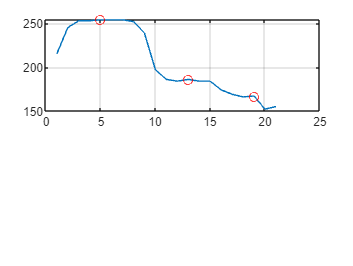

% find out horizontal resolution
group1_6_x_lim=[305 325];
group1_6_y_cen=125;
% plot the peak for image intensity 
figure;
subplot(211);
    I = bw_img(group1_6_y_cen,group1_6_x_lim(1):group1_6_x_lim(2));  % 1D array extracted from the 2D array.
    I=flip(I,1);
    I=double(I);
    plot(I);
    [pks,locs] = findpeaks(I);  % find peaks.
    line(locs,pks,'linestyle','none','marker','o','color','r');
    grid on;

For larger zoom level, the influence of the external light source becomes more obvious based on the observation of the original sample image. Therefore, the influence of the external light source becomes more and more obvious.

For vertical direction, in this case, in group 1, the peak-to-valley ratio follows the 25% dip Rayleigh criterion. Therefore, the resolution of the camera falls in group 1 of USAF resolution target, and based on the plot, the line starts to decline at the thrid set of serial waves. Therefore, the resolution falls in element 5 in group 1.

Its resolution in this case can be calculated based on the resolution formula for USAF 1951 target as follow:

group=1; % group 2 in USAF target
element=5; % element 4 in group 2
resolution=2^(group+(element-1)/6);
msg=strcat("The resolution is ", string(resolution), " lp/mm (in vertical)");
msg

msg = "The resolution is 3.1748 lp/mm (in vertical)"

For horizontal direction, in group 1, the peak-to-valley ratio follows the 25% Rayleigh criterion is in element 1 in group 6. Therefore,

group=1; % group 2 in USAF target
element=6; % element 3 in group 2
resolution=2^(group+(element-1)/6);
msg=strcat("The resolution is ", string(resolution), " lp/mm (in horizontal)");
msg

msg = "The resolution is 3.5636 lp/mm (in horizontal)"

**DIfferent Background Testing:**

In the previous section, the target is placed in the blackground. Therefore, the visibility of the target is mainly due to the relfection of the light source. In this section, a different background is placed (white background) to see the influence of the background on the measurement of the resolution.

**Zoom level 1 in white background:**

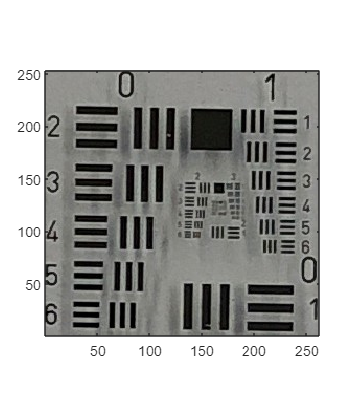

clear all
% read in testing image for zoom level 1 in black ground
allfiles=dir("Test_Images/zoom_lvl_b1_*.JPG");
num_files=length(allfiles); % find out how many files in the directory

% read in image
curr_file=allfiles(1).name; % get out the filename of the current image
curr_img=imread(string(curr_file)); % read in the image 
% conduct analysis on image
curr_img=double(curr_img); % convert the image to double type
[num_px,num_py] = size(curr_img); % get the number of pixel in x and y axis
% visualization of the image
figure(4);
curr_img=flip(curr_img,2);
ver_img=flipud(curr_img);
ori_img=flip(ver_img,2);
imagesc(uint8(ori_img))
set(gca,'ydir','normal');  
axis image;  

For sample in white background, unlike in the black background, the sample does not get affected as much as it does when it's placed in the dark background since the visibility of the targets on the sample does not depend on the light reflectation from external light source. Also due to that, the target since to have better visibility, which might due to the elimination of the refraction of the external light source.

For this case, the resolution falls approximately in the 5th to 6th element in group 2, which is slightly better than it shows in the dark background.

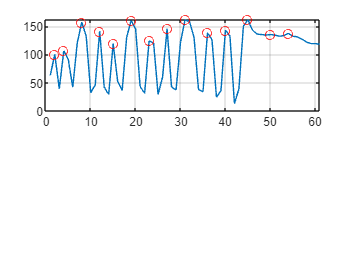

test_img=flip(curr_img,2); % flip the image to get the image to the right orientation to the coordinate

% mark out the center of the bar
group2_x_cen=139; % group 1 x center
group2_y_lim=[90 150]; % group 1 limit range

% convert the image to grayscale image to view its intensity 
bw_img=rgb2gray(uint8(test_img));
% plot the peak for image intensity 
figure;
subplot(211);
    I = bw_img(group2_y_lim(1):group2_y_lim(2),group2_x_cen);  % 1D array extracted from the 2D array.
    I=flip(I,1);
    I=double(I);
    plot(I);
    [pks,locs] = findpeaks(I);  % find peaks.
    line(locs,pks,'linestyle','none','marker','o','color','r');
    grid on;

The same procedure follows for horizontal direction:

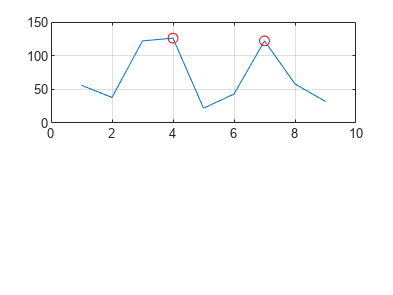

% find out horizontal resolution
group2_3_x_lim=[146 154];
group2_3_y_cen=128;
% plot the peak for image intensity 
figure;
subplot(211);
    I = bw_img(group1_6_y_cen,group1_6_x_lim(1):group1_6_x_lim(2));  % 1D array extracted from the 2D array.
    I=flip(I,1);
    I=double(I);
    plot(I);
    [pks,locs] = findpeaks(I);  % find peaks.
    line(locs,pks,'linestyle','none','marker','o','color','r');
    grid on;

From the above, it can be seen that the result of the resolution measurment gets slightly better in white background, and its resolution can be calculated as:

group=2; % group 2 in USAF target
element=5; % element 4 in group 2
resolution=2^(group+(element-1)/6);
msg=strcat("The resolution is ", string(resolution), " lp/mm (in vertical)");
msg

msg = "The resolution is 6.3496 lp/mm (in vertical)"

group=2; % group 2 in USAF target
element=3; % element 3 in group 2
resolution=2^(group+(element-1)/6);
msg=strcat("The resolution is ", string(resolution), " lp/mm (in horizontal)");
msg

msg = "The resolution is 5.0397 lp/mm (in horizontal)"

**Zoon level 2 in white background:**

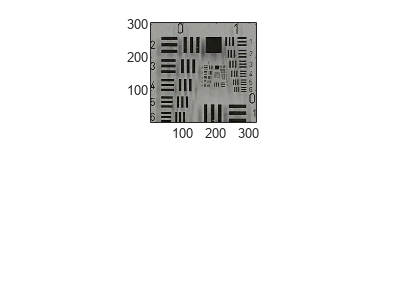

clear all
% read in testing image for zoom level 1 in black ground
allfiles=dir("Test_Images/zoom_lvl_b2_*.JPG");
num_files=length(allfiles); % find out how many files in the directory

% read in image
curr_file=allfiles(1).name; % get out the filename of the current image
curr_img=imread(string(curr_file)); % read in the image 
% conduct analysis on image
curr_img=double(curr_img); % convert the image to double type
[num_px,num_py] = size(curr_img); % get the number of pixel in x and y axis
% visualization of the image
figure(5);
curr_img=flip(curr_img,2);
ver_img=flipud(curr_img);
ori_img=flip(ver_img,2);
imagesc(uint8(ori_img))
set(gca,'ydir','normal');  
axis image;  

The same procedure for vertical direction measurement in this case as well:

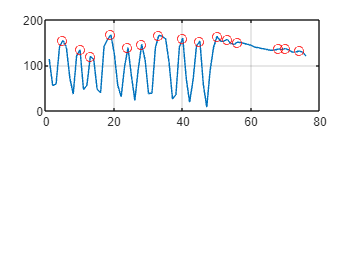

test_img=flip(curr_img,2); % flip the image to get the image to the right orientation to the coordinate

% mark out the center of the bar
group2_x_cen=169; % group 1 x center
group2_y_lim=[105 180]; % group 1 limit range

% convert the image to grayscale image to view its intensity 
bw_img=rgb2gray(uint8(test_img));
% plot the peak for image intensity 
figure;
subplot(211);
    I = bw_img(group2_y_lim(1):group2_y_lim(2),group2_x_cen);  % 1D array extracted from the 2D array.
    I=flip(I,1);
    I=double(I);
    plot(I);
    [pks,locs] = findpeaks(I);  % find peaks.
    line(locs,pks,'linestyle','none','marker','o','color','r');
    grid on;

In this case, the resolution falls approximately in element 4 of group 2.

For horizontal direction measurement,

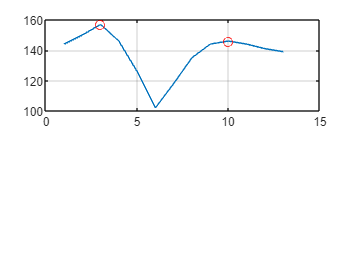

% find out horizontal resolution
group2_5_x_lim=[172 184];
group2_5_y_cen=126;
% plot the peak for image intensity 
figure;
subplot(211);
    I = bw_img(group2_5_y_cen,group2_5_x_lim(1):group2_5_x_lim(2));  % 1D array extracted from the 2D array.
    I=flip(I,1);
    I=double(I);
    plot(I);
    [pks,locs] = findpeaks(I);  % find peaks.
    line(locs,pks,'linestyle','none','marker','o','color','r');
    grid on;

For this section, the resolution of vertical and horizontal direction are:

group=2; % group 2 in USAF target
element=5; % element 4 in group 2
resolution=2^(group+(element-1)/6);
msg=strcat("The resolution is ", string(resolution), " lp/mm (in vertical)");
msg

msg = "The resolution is 6.3496 lp/mm (in vertical)"

group=2; % group 2 in USAF target
element=5; % element 3 in group 2
resolution=2^(group+(element-1)/6);
msg=strcat("The resolution is ", string(resolution), " lp/mm (in horizontal)");
msg

msg = "The resolution is 6.3496 lp/mm (in horizontal)"

**Zoom level 3 in white background:**

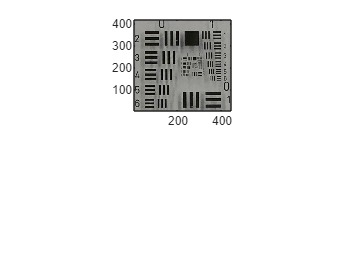

clear all
% read in testing image for zoom level 1 in black ground
allfiles=dir("Test_Images/zoom_lvl_b3_*.JPG");
num_files=length(allfiles); % find out how many files in the directory

% read in image
curr_file=allfiles(1).name; % get out the filename of the current image
curr_img=imread(string(curr_file)); % read in the image 
% conduct analysis on image
curr_img=double(curr_img); % convert the image to double type
[num_px,num_py] = size(curr_img); % get the number of pixel in x and y axis
% visualization of the image
figure(5);
curr_img=flip(curr_img,2);
ver_img=flipud(curr_img);
ori_img=flip(ver_img,2);
imagesc(uint8(ori_img))
set(gca,'ydir','normal');  
axis image; 

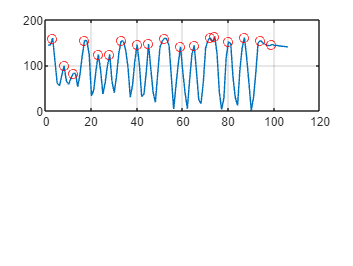

test_img=flip(curr_img,2); % flip the image to get the image to the right orientation to the coordinate

% mark out the center of the bar
group2_x_cen=230; % group 1 x center
group2_y_lim=[155 260]; % group 1 limit range

% convert the image to grayscale image to view its intensity 
bw_img=rgb2gray(uint8(test_img));
% plot the peak for image intensity 
figure;
subplot(211);
    I = bw_img(group2_y_lim(1):group2_y_lim(2),group2_x_cen);  % 1D array extracted from the 2D array.
    I=flip(I,1);
    I=double(I);
    plot(I);
    [pks,locs] = findpeaks(I);  % find peaks.
    line(locs,pks,'linestyle','none','marker','o','color','r');
    grid on;

For this testing, the resolution group falls approximately in 6th element of group 2 in vertical direction.

As for horizontal direction,

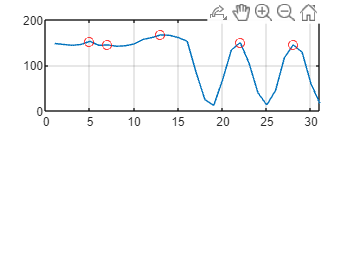

% find out horizontal resolution
group2_5_x_lim=[230 260];
group2_5_y_cen=180;
% plot the peak for image intensity 
figure;
subplot(211);
    I = bw_img(group2_5_y_cen,group2_5_x_lim(1):group2_5_x_lim(2));  % 1D array extracted from the 2D array.
    I=flip(I,1);
    I=double(I);
    plot(I);
    [pks,locs] = findpeaks(I);  % find peaks.
    line(locs,pks,'linestyle','none','marker','o','color','r');
    grid on;

For horizontal direction resolution, the resolution falls approximately in the 5th element of group 2.

From the above observation, the resolution of the image can be calculated as:

group=2; % group 2 in USAF target
element=5; % element 5 in group 2
resolution=2^(group+(element-1)/6);
msg=strcat("The resolution is ", string(resolution), " lp/mm (in vertical)");
msg

msg = "The resolution is 6.3496 lp/mm (in vertical)"

group=2; % group 2 in USAF target
element=5; % element 5 in group 2
resolution=2^(group+(element-1)/6);
msg=strcat("The resolution is ", string(resolution), " lp/mm (in horizontal)");
msg

msg = "The resolution is 6.3496 lp/mm (in horizontal)"

**Different light condition:**

For all samples taken in the previous section, all samples are taken in no flashlight condition. In this section, the same zoom levels and background settings are repeated except for this time, the flashlight of the camera is utilized.

**Zoom level 1 with black background (flashlight on):**

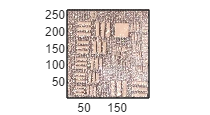

clear all
% read in testing image for zoom level 1 in black ground
allfiles=dir("Test_Images/bright_*.JPG");
num_files=length(allfiles); % find out how many files in the directory

% read in image
curr_file=allfiles(1).name; % get out the filename of the current image
curr_img=imread(string(curr_file)); % read in the image 
% conduct analysis on image
curr_img=double(curr_img); % convert the image to double type
[num_px,num_py] = size(curr_img); % get the number of pixel in x and y axis
% visualization of the image
figure(1);
curr_img=flip(curr_img,2);
ver_img=flipud(curr_img);
ori_img=flip(ver_img,2);
imagesc(uint8(ori_img))
set(gca,'ydir','normal');  
axis image;  

From the above observation, the resolution of the image becomes even worse due to the enhancement ofthe external light source. From the above picture, the group 2 and 3 elements are entirely invisible. From the above observation, only the element in group 0 is slightly visible compared to other elements in other groups.

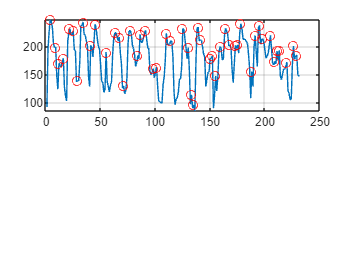

test_img=flip(curr_img,2); % flip the image to get the image to the right orientation to the coordinate

% mark out the center of the bar
group1_x_cen=50; % group 1 x center
group1_y_lim=[10 240]; % group 1 limit range

% convert the image to grayscale image to view its intensity 
bw_img=rgb2gray(uint8(test_img));
% plot the peak for image intensity 
figure;
subplot(211);
    I = bw_img(group1_y_lim(1):group1_y_lim(2),group1_x_cen);  % 1D array extracted from the 2D array.
    I=flip(I,1);
    I=double(I);
    plot(I);
    [pks,locs] = findpeaks(I);  % find peaks.
    line(locs,pks,'linestyle','none','marker','o','color','r');
    grid on;

As predicted from the direct observation, the visibility of the image is largely affected to the flshlight that has been utilized. Therefore, the wave patterns becomes more noisey and more difficult to observe.

Same procedure follows in horizontal direction,

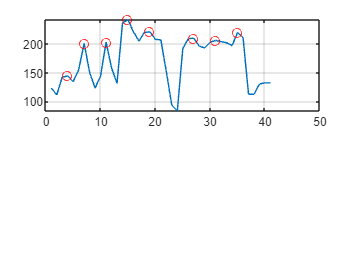

% find out horizontal resolution
group1_4_x_lim=[65 105];
group1_4_y_cen=100;
% plot the peak for image intensity 
figure;
subplot(211);
    I = bw_img(group1_4_y_cen,group1_4_x_lim(1):group1_4_x_lim(2));  % 1D array extracted from the 2D array.
    I=flip(I,1);
    I=double(I);
    plot(I);
    [pks,locs] = findpeaks(I);  % find peaks.
    line(locs,pks,'linestyle','none','marker','o','color','r');
    grid on;

The observation for flashlight sample in black background is more difficult to observe due to the noise introduced by the flashlight of the camera. The vertical resolution located approximately in element 4 in group 1 and as well asthe horizontal resolution.

group=1; % group 1 in USAF target
element=4; % element 4 in group 2
resolution=2^(group+(element-1)/6);
msg=strcat("The resolution is ", string(resolution), " lp/mm (in vertical)");
msg

msg = "The resolution is 2.8284 lp/mm (in vertical)"

group=1; % group 1 in USAF target
element=4; % element 4 in group 2
resolution=2^(group+(element-1)/6);
msg=strcat("The resolution is ", string(resolution), " lp/mm (in horizontal)");
msg

msg = "The resolution is 2.8284 lp/mm (in horizontal)"

**Zoom level 2 with black background (flashlight on):**

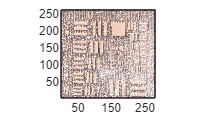

clear all
% read in testing image for zoom level 1 in black ground
allfiles=dir("Test_Images/bright_*.JPG");
num_files=length(allfiles); % find out how many files in the directory

% read in image
curr_file=allfiles(2).name; % get out the filename of the current image
curr_img=imread(string(curr_file)); % read in the image 
% conduct analysis on image
curr_img=double(curr_img); % convert the image to double type
[num_px,num_py] = size(curr_img); % get the number of pixel in x and y axis
% visualization of the image
figure(1);
curr_img=flip(curr_img,2);
ver_img=flipud(curr_img);
ori_img=flip(ver_img,2);
imagesc(uint8(ori_img))
set(gca,'ydir','normal');  
axis image;

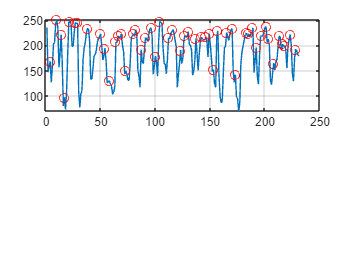

test_img=flip(curr_img,2); % flip the image to get the image to the right orientation to the coordinate

% mark out the center of the bar
group1_x_cen=55; % group 1 x center
group1_y_lim=[10 240]; % group 1 limit range

% convert the image to grayscale image to view its intensity 
bw_img=rgb2gray(uint8(test_img));
% plot the peak for image intensity 
figure;
subplot(211);
    I = bw_img(group1_y_lim(1):group1_y_lim(2),group1_x_cen);  % 1D array extracted from the 2D array.
    I=flip(I,1);
    I=double(I);
    plot(I);
    [pks,locs] = findpeaks(I);  % find peaks.
    line(locs,pks,'linestyle','none','marker','o','color','r');
    grid on;

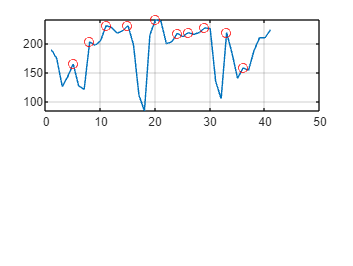

% find out horizontal resolution
group1_4_x_lim=[80 120];
group1_4_y_cen=100;
% plot the peak for image intensity 
figure;
subplot(211);
    I = bw_img(group1_4_y_cen,group1_4_x_lim(1):group1_4_x_lim(2));  % 1D array extracted from the 2D array.
    I=flip(I,1);
    I=double(I);
    plot(I);
    [pks,locs] = findpeaks(I);  % find peaks.
    line(locs,pks,'linestyle','none','marker','o','color','r');
    grid on;

From the above observation, the resolution can be calculated as:

group=1; % group 1 in USAF target
element=4; % element 4 in group 2
resolution=2^(group+(element-1)/6);
msg=strcat("The resolution is ", string(resolution), " lp/mm (in vertical)");
msg

msg = "The resolution is 2.8284 lp/mm (in vertical)"

group=1; % group 1 in USAF target
element=4; % element 4 in group 1
resolution=2^(group+(element-1)/6);
msg=strcat("The resolution is ", string(resolution), " lp/mm (in horizontal)");
msg

msg = "The resolution is 2.8284 lp/mm (in horizontal)"

**Zoom level 3 with black background (flashlight on):**

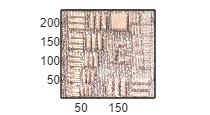

clear all
% read in testing image for zoom level 1 in black ground
allfiles=dir("Test_Images/bright_*.JPG");
num_files=length(allfiles); % find out how many files in the directory

% read in image
curr_file=allfiles(3).name; % get out the filename of the current image
curr_img=imread(string(curr_file)); % read in the image 
% conduct analysis on image
curr_img=double(curr_img); % convert the image to double type
[num_px,num_py] = size(curr_img); % get the number of pixel in x and y axis
% visualization of the image
figure(1);
curr_img=flip(curr_img,2);
ver_img=flipud(curr_img);
ori_img=flip(ver_img,2);
imagesc(uint8(ori_img))
set(gca,'ydir','normal');  
axis image;

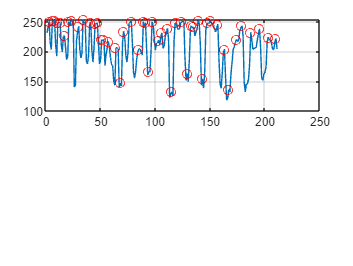

test_img=flip(curr_img,2); % flip the image to get the image to the right orientation to the coordinate

% mark out the center of the bar
group1_x_cen=38; % group 1 x center
group1_y_lim=[10 220]; % group 1 limit range

% convert the image to grayscale image to view its intensity 
bw_img=rgb2gray(uint8(test_img));
% plot the peak for image intensity 
figure;
subplot(211);
    I = bw_img(group1_y_lim(1):group1_y_lim(2),group1_x_cen);  % 1D array extracted from the 2D array.
    I=flip(I,1);
    I=double(I);
    plot(I);
    [pks,locs] = findpeaks(I);  % find peaks.
    line(locs,pks,'linestyle','none','marker','o','color','r');
    grid on;

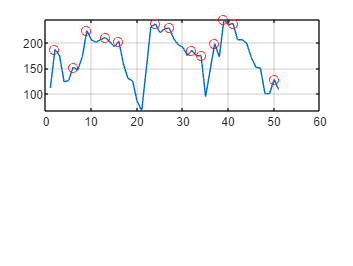

% find out horizontal resolution
group1_4_x_lim=[60 110];
group1_4_y_cen=100;
% plot the peak for image intensity 
figure;
subplot(211);
    I = bw_img(group1_4_y_cen,group1_4_x_lim(1):group1_4_x_lim(2));  % 1D array extracted from the 2D array.
    I=flip(I,1);
    I=double(I);
    plot(I);
    [pks,locs] = findpeaks(I);  % find peaks.
    line(locs,pks,'linestyle','none','marker','o','color','r');
    grid on;

From the above observation, we can conclude:

group=1; % group 1 in USAF target
element=4; % element 4 in group 2
resolution=2^(group+(element-1)/6);
msg=strcat("The resolution is ", string(resolution), " lp/mm (in vertical)");
msg

msg = "The resolution is 2.8284 lp/mm (in vertical)"

group=1; % group 1 in USAF target
element=4; % element 4 in group 1
resolution=2^(group+(element-1)/6);
msg=strcat("The resolution is ", string(resolution), " lp/mm (in horizontal)");
msg

msg = "The resolution is 2.8284 lp/mm (in horizontal)"

**Zoom level 1 with white background (flashlight on):**

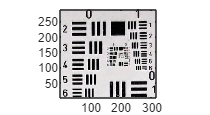

clear all
% read in testing image for zoom level 1 in black ground
allfiles=dir("Test_Images/bright_w_*.JPG");
num_files=length(allfiles); % find out how many files in the directory

% read in image
curr_file=allfiles(1).name; % get out the filename of the current image
curr_img=imread(string(curr_file)); % read in the image 
% conduct analysis on image
curr_img=double(curr_img); % convert the image to double type
[num_px,num_py] = size(curr_img); % get the number of pixel in x and y axis
% visualization of the image
figure(1);
curr_img=flip(curr_img,2);
ver_img=flipud(curr_img);
ori_img=flip(ver_img,2);
imagesc(uint8(ori_img))
set(gca,'ydir','normal');  
axis image;

From the above image, it can be seen that in contrast to the situation of the dark backgroun case, the target resolution get enhanced due to the enhancement of the external light source. The resolution of the camera seen to get even better.

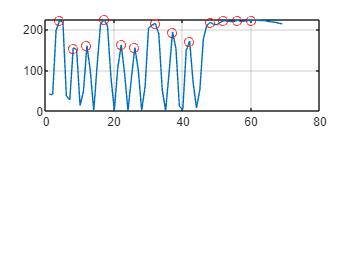

test_img=flip(curr_img,2); % flip the image to get the image to the right orientation to the coordinate

% mark out the center of the bar
group1_x_cen=167; % group 1 x center
group1_y_lim=[100 168]; % group 1 limit range

% convert the image to grayscale image to view its intensity 
bw_img=rgb2gray(uint8(test_img));
% plot the peak for image intensity 
figure;
subplot(211);
    I = bw_img(group1_y_lim(1):group1_y_lim(2),group1_x_cen);  % 1D array extracted from the 2D array.
    I=flip(I,1);
    I=double(I);
    plot(I);
    [pks,locs] = findpeaks(I);  % find peaks.
    line(locs,pks,'linestyle','none','marker','o','color','r');
    grid on;

From the above observation, the resolution of the image get into the 4th element of group 2 in vertical direction.

The same procedure follows in horizontal direction:

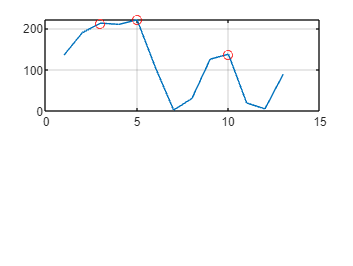

% find out horizontal resolution
group2_4_x_lim=[172 184];
group2_4_y_cen=131;
% plot the peak for image intensity 
figure;
subplot(211);
    I = bw_img(group2_4_y_cen,group2_4_x_lim(1):group2_4_x_lim(2));  % 1D array extracted from the 2D array.
    I=flip(I,1);
    I=double(I);
    plot(I);
    [pks,locs] = findpeaks(I);  % find peaks.
    line(locs,pks,'linestyle','none','marker','o','color','r');
    grid on;

For horizontal direction, the resolution of the image falls approximately in 4th element of group 2.

The overall resolution of the camera can be calculated as:

group=2; % group 1 in USAF target
element=4; % element 4 in group 2
resolution=2^(group+(element-1)/6);
msg=strcat("The resolution is ", string(resolution), " lp/mm (in vertical)");
msg

msg = "The resolution is 5.6569 lp/mm (in vertical)"

group=2; % group 1 in USAF target
element=4; % element 4 in group 1
resolution=2^(group+(element-1)/6);
msg=strcat("The resolution is ", string(resolution), " lp/mm (in horizontal)");
msg

msg = "The resolution is 5.6569 lp/mm (in horizontal)"

**Zoom level 2 with white background (flashlight on):**

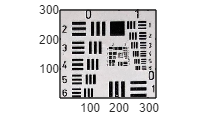

clear all
% read in testing image for zoom level 1 in black ground
allfiles=dir("Test_Images/bright_w_*.JPG");
num_files=length(allfiles); % find out how many files in the directory

% read in image
curr_file=allfiles(2).name; % get out the filename of the current image
curr_img=imread(string(curr_file)); % read in the image 
% conduct analysis on image
curr_img=double(curr_img); % convert the image to double type
[num_px,num_py] = size(curr_img); % get the number of pixel in x and y axis
% visualization of the image
figure(1);
curr_img=flip(curr_img,2);
ver_img=flipud(curr_img);
ori_img=flip(ver_img,2);
imagesc(uint8(ori_img))
set(gca,'ydir','normal');  
axis image;

The same procedure is followed in investigating this sample:

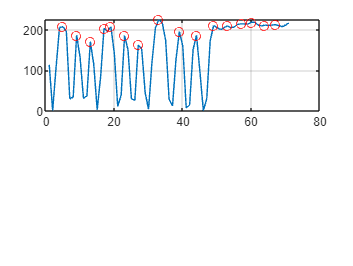

test_img=flip(curr_img,2); % flip the image to get the image to the right orientation to the coordinate

% mark out the center of the bar
group2_x_cen=170; % group 1 x center
group2_y_lim=[105 175]; % group 1 limit range

% convert the image to grayscale image to view its intensity 
bw_img=rgb2gray(uint8(test_img));
% plot the peak for image intensity 
figure;
subplot(211);
    I = bw_img(group2_y_lim(1):group2_y_lim(2),group2_x_cen);  % 1D array extracted from the 2D array.
    I=flip(I,1);
    I=double(I);
    plot(I);
    [pks,locs] = findpeaks(I);  % find peaks.
    line(locs,pks,'linestyle','none','marker','o','color','r');
    grid on;

From the above testing, it can be seen that the resolution of the image falls again approximately in the 4th element of group 2.

The same procedure follows for horizontal direction,

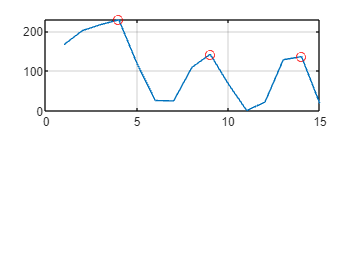

% find out horizontal resolution
group2_4_x_lim=[176 190];
group2_4_y_cen=136;
% plot the peak for image intensity 
figure;
subplot(211);
    I = bw_img(group2_4_y_cen,group2_4_x_lim(1):group2_4_x_lim(2));  % 1D array extracted from the 2D array.
    I=flip(I,1);
    I=double(I);
    plot(I);
    [pks,locs] = findpeaks(I);  % find peaks.
    line(locs,pks,'linestyle','none','marker','o','color','r');
    grid on;

As for the resolution of horizontal direction, the resolution falls approximately in 4th element in group 2. 

From that, we can calculate the following resolutions:

group=2; % group 1 in USAF target
element=4; % element 4 in group 2
resolution=2^(group+(element-1)/6);
msg=strcat("The resolution is ", string(resolution), " lp/mm (in vertical)");
msg

msg = "The resolution is 5.6569 lp/mm (in vertical)"

group=2; % group 1 in USAF target
element=4; % element 4 in group 1
resolution=2^(group+(element-1)/6);
msg=strcat("The resolution is ", string(resolution), " lp/mm (in horizontal)");
msg

msg = "The resolution is 5.6569 lp/mm (in horizontal)"

**Zoom level 3 with white background (flashlight on):**

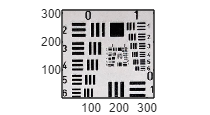

clear all
% read in testing image for zoom level 1 in black ground
allfiles=dir("Test_Images/bright_w_*.JPG");
num_files=length(allfiles); % find out how many files in the directory

% read in image
curr_file=allfiles(3).name; % get out the filename of the current image
curr_img=imread(string(curr_file)); % read in the image 
% conduct analysis on image
curr_img=double(curr_img); % convert the image to double type
[num_px,num_py] = size(curr_img); % get the number of pixel in x and y axis
% visualization of the image
figure(1);
curr_img=flip(curr_img,2);
ver_img=flipud(curr_img);
ori_img=flip(ver_img,2);
imagesc(uint8(ori_img))
set(gca,'ydir','normal');  
axis image;

From the above image, it can be seen that in contrast to the situation of the dark backgroun case, the target resolution get enhanced due to the enhancement of the external light source. The resolution of the camera seen to get even better.

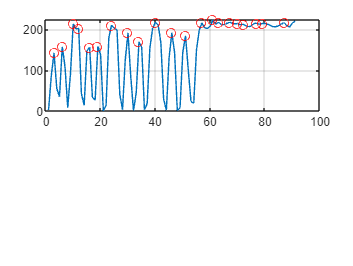

test_img=flip(curr_img,2); % flip the image to get the image to the right orientation to the coordinate

% mark out the center of the bar
group2_x_cen=168; % group 1 x center
group2_y_lim=[100 190]; % group 1 limit range

% convert the image to grayscale image to view its intensity 
bw_img=rgb2gray(uint8(test_img));
% plot the peak for image intensity 
figure;
subplot(211);
    I = bw_img(group2_y_lim(1):group2_y_lim(2),group2_x_cen);  % 1D array extracted from the 2D array.
    I=flip(I,1);
    I=double(I);
    plot(I);
    [pks,locs] = findpeaks(I);  % find peaks.
    line(locs,pks,'linestyle','none','marker','o','color','r');
    grid on;

From the above observation, the resolution of the image get into the 4th element of group 2 in vertical direction.

The same procedure follows in horizontal direction:

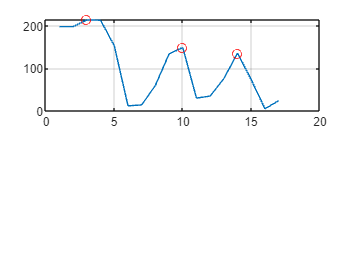

% find out horizontal resolution
group2_4_x_lim=[174 190];
group2_4_y_cen=140;
% plot the peak for image intensity 
figure;
subplot(211);
    I = bw_img(group2_4_y_cen,group2_4_x_lim(1):group2_4_x_lim(2));  % 1D array extracted from the 2D array.
    I=flip(I,1);
    I=double(I);
    plot(I);
    [pks,locs] = findpeaks(I);  % find peaks.
    line(locs,pks,'linestyle','none','marker','o','color','r');
    grid on;

For horizontal direction, the resolution of the image falls approximately in 4th element of group 2.

The overall resolution of the camera can be calculated as:

group=2; % group 1 in USAF target
element=4; % element 4 in group 2
resolution=2^(group+(element-1)/6);
msg=strcat("The resolution is ", string(resolution), " lp/mm (in vertical)");
msg

msg = "The resolution is 5.6569 lp/mm (in vertical)"

group=2; % group 1 in USAF target
element=4; % element 4 in group 1
resolution=2^(group+(element-1)/6);
msg=strcat("The resolution is ", string(resolution), " lp/mm (in horizontal)");
msg

msg = "The resolution is 5.6569 lp/mm (in horizontal)"

**Conclusion of the Experiment:**

The previous sections demonstrate the experiment of measuring the resolution in horizontal and vertical direction. For the experiment, the factor of background color, zoom levels and the utilization of flashlight are all taken into account. 

To sum up, the experiment the table following shows all the results with different settings:

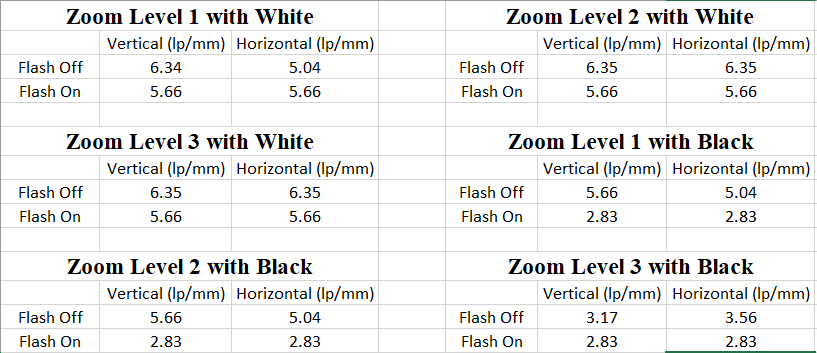

From the above results, the following conclusions can be made:

- The utlilzation of the flashlight can deteriorate the resolution of the device camera

- Overall, the resolution in white background performs better

- Different zoom level of camera doesn't affect the resoluton significantly.

To take the results part, the vertical resolution of 6.35 lp/mm and the horizontal resolution of 5.04 lp/mm is utilized.

**PIxel Size of Camera:**

The pixel size of the camera for iPhone 8 can be found at: [https://www.ephotozine.com/article/apple-iphone-8-plus-camera-review--32052/specifications.](https://www.ephotozine.com/article/apple-iphone-8-plus-camera-review--32052/specifications.)

Its camera sensor is 1/3 inch.

**Virtual Pixel Size:**

To calculate the virtual pixel size of the camera, it can be shown as:

line_width_ver=78.74e-3; % line width for vertical (mm)
line_width_hor=99.21e-3; % line width for horizontal (mm)
ver_line=line_width_ver*2*6.35;
hor_line=line_width_hor*2*5.04;

% calculate the virtual pixel size
cam_sen=1/3*25.4;
ver_virtual_size=line_width_ver*cam_sen;
hor_virtual_size=line_width_hor*cam_sen;
msg=strcat("The vertical virtual pixel size is: ",string(ver_virtual_size), " mm.");
msg

msg = "The vertical virtual pixel size is: 0.66667 mm."

msg=strcat("The horizontal virtual pixel size is: ",string(hor_virtual_size), " mm.");
msg

msg = "The horizontal virtual pixel size is: 0.83998 mm."

**Magnification of Camera:**

magn=ver_virtual_size/cam_sen; % in vertical direction
magn2=hor_virtual_size/cam_sen; % in horizontal direction
magn=mean([magn magn2],'all')

magn = 0.0890

msg=strcat("The vertical virtual pixel size is: ",string(magn));
msg

msg = "The vertical virtual pixel size is: 0.088975"

**Kernel Size of Camera:**

ver_kern=1/magn*cam_sen*10^(3); % vertical kernel size
hor_kern=1/magn2*cam_sen*10^(3); % horizontal kernel size
msg=strcat("The vertical virtual kernel size is: ",string(ver_kern), "um");
msg

msg = "The vertical virtual kernel size is: 95157.8159um"

msg=strcat("The vertical horizontal kernel size is: ",string(hor_kern), "um");
msg

msg = "The vertical horizontal kernel size is: 85340.8595um"

Based on the previous observation that the zoom level doesn't change the resolution of the camera, it can be seen that the change of zoom levels doesn't necessary effect the kernel size of the camera.

**Numerical Aperture of Camera:**

wavelength=[500e-3 700e-3]; % wavelengths range (um)
% for vertical numberical aperture range
na_ver=wavelength/(2*ver_line);
msg=strcat("The vertical numerical aperture is: ");
na_ver

na_ver =     0.2500    0.3500


% for horizontal numberical aperture range
na_hor=wavelength/(2*hor_line);
msg=strcat("The horizontal numerical aperture is: ");
na_hor

na_hor =     0.2500    0.3500


For searching online, the official numerical aperture is f/1.8 aperture.

The relationship between the f number and numerical aperture can be defined as:

NA = 1/(2*f/number)

NA=1/(2*1.8)

NA = 0.2778